## Survival ratio computation by bistable using LHS

### LHS for parameters

clear;clc;
% load parameters
par_init = importdata('par_base_IAV_clock_values.txt');
par_init = par_init.data;

ratio = 0.04;
N = 100;  % parameter set number

par_bound = zeros(2, length(par_init));
par_bound(1, :) = par_init .* (1 - ratio);
par_bound(2, :) = par_init .* (1 + ratio);

lhs_rad = lhsdesign(N, length(par_bound));
par_lhs = par_bound(1, :) + lhs_rad .* (par_bound(2, :) - par_bound(1, :));

% write lhs parameters to file
file_par = fopen('lhs_par.txt', 'w');
for i = 1:N
    fprintf(file_par, '%.10f ', par_lhs(i, :));
    fprintf(file_par, '\n');
end
fclose(file_par);

### Run ODEs

% load immune parameter set
par_lhs = importdata('lhs_par.txt');

% load clock parameters
par_clock = load('par_clock.csv');

% load inflammation parameters
par_infla = importdata('par_infla.txt');
par_infla = par_infla.data;

par_num = 100;
var_num = 25;

y0 = zeros(25, 1);
y0_IAV = importdata('init_base.txt');
y0_IAV = y0_IAV.data;
for i = 13:25
    y0(i) = y0_IAV(i - 12);
end

tmax = 2000;
tspan = 0:1:tmax;

% run odes for ZT5
y5s = zeros(length(tspan), var_num, par_num);
t_IAV_5 = 505;
parfor i = 1:par_num
    [~, y5s(:, :, i)] = ode15s(@ODE_Clock_IAV, tspan, y0, [], par_clock, par_lhs(i, :), t_IAV_5);
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to the parallel pool (number of workers: 12).



% run odes for ZT11
y11s = zeros(length(tspan), var_num, par_num);
t_IAV_11 = 511;
parfor i = 1:par_num
    [~, y11s(:, :, i)] = ode15s(@ODE_Clock_IAV, tspan, y0, [], par_clock, par_lhs(i, :), t_IAV_11);
end

% run odes for ZT17
y17s = zeros(length(tspan), var_num, par_num);
t_IAV_17 = 517;
parfor i = 1:par_num
    [~, y17s(:, :, i)] = ode15s(@ODE_Clock_IAV, tspan, y0, [], par_clock, par_lhs(i, :), t_IAV_17);
end

% run odes for ZT23
y23s = zeros(length(tspan), var_num, par_num);
t_IAV_23 = 499;
parfor i = 1:par_num
    [~, y23s(:, :, i)] = ode15s(@ODE_Clock_IAV, tspan, y0, [], par_clock, par_lhs(i, :), t_IAV_23);
end

% run odes for ZT11 with clock knock out
y11_ko = zeros(length(tspan), var_num, par_num);
t_IAV_11 = 511;
parfor i = 1:par_num
    [~, y11_ko(:, :, i)] = ode15s(@ODE_Clock_KO_IAV, tspan, y0, [], par_clock, par_lhs(i, :), t_IAV_11);
end

% run odes for ZT23 with clock knock out
y23_ko = zeros(length(tspan), var_num, par_num);
t_IAV_23 = 499;
parfor i = 1:par_num
    [~, y23_ko(:, :, i)] = ode15s(@ODE_Clock_KO_IAV, tspan, y0, [], par_clock, par_lhs(i, :), t_IAV_23);
end

### Plot figuires

plot time evolution

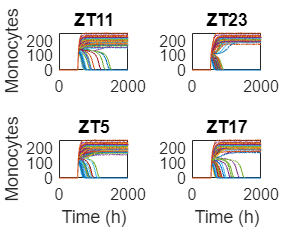

figure;
subplot(2, 2, 1); hold on; set(gca,'Fontsize',12); box on;
for i = 1:par_num
    plot(tspan, y11s(:, 17, i));
end
ylabel('Monocytes');
title('ZT11');
set(gcf, 'unit', 'centimeters', 'position', [10 5 8 6]);
hold off;

subplot(2, 2, 2); hold on; set(gca,'Fontsize',12); box on;
for i = 1:par_num
    plot(tspan, y23s(:, 17, i));
end
title('ZT23');
set(gcf, 'unit', 'centimeters', 'position', [10 5 8 6]);
hold off;

subplot(2, 2, 3); hold on; set(gca,'Fontsize',12); box on;
for i = 1:par_num
    plot(tspan, y5s(:, 17, i));
end
xlabel('Time (h)'); ylabel('Monocytes');
title('ZT5');
set(gcf, 'unit', 'centimeters', 'position', [10 5 8 6]);
hold off;

subplot(2, 2, 4); hold on; set(gca,'Fontsize',12); box on;
for i = 1:par_num
    plot(tspan, y17s(:, 17, i));
end
xlabel('Time (h)');
title('ZT17');
set(gcf, 'unit', 'centimeters', 'position', [10 5 8 6]);
hold off;

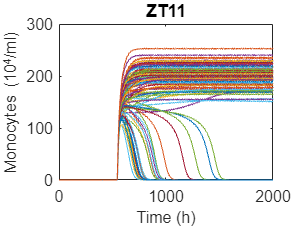

figure; hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
for i = 1:par_num
    plot(tspan, y11s(:, 17, i));
end
ylabel('Monocytes');
title('ZT11');
% xlim([-10 400]);
% xticks(0:100:400);
xlabel('Time (h)','Fontsize',12, 'FontName', 'Arial'); ylabel('Monocytes (10^4/ml)','Fontsize',12, 'FontName', 'Arial');
% legend('CT11', 'CT23', 'Box', 'off', 'Fontsize',12, 'FontName', 'Arial', 'Location', 'east');
set(gcf, 'unit', 'centimeters', 'position', [10 5 8 6]);
hold off;

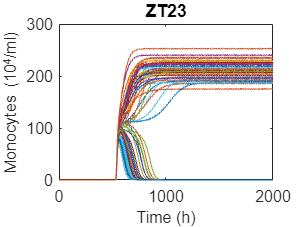


figure; hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
for i = 1:par_num
    plot(tspan, y23s(:, 17, i));
end
ylabel('Monocytes');
title('ZT23');
% xlim([-10 400]);
% xticks(0:100:400);
xlabel('Time (h)','Fontsize',12, 'FontName', 'Arial'); ylabel('Monocytes (10^4/ml)','Fontsize',12, 'FontName', 'Arial');
% legend('CT11', 'CT23', 'Box', 'off', 'Fontsize',12, 'FontName', 'Arial', 'Location', 'east');
set(gcf, 'unit', 'centimeters', 'position', [10 5 8 6]);
hold off;

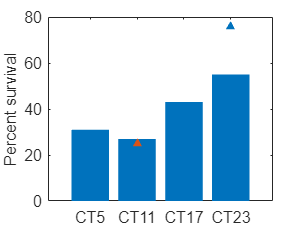

% plot survival ratios
survival_num_5 = 0;
survival_num_11 = 0;
survival_num_17 = 0;
survival_num_23 = 0;
survival_num_11_ko = 0;
survival_num_23_ko = 0;
for i = 1:par_num
    if y5s(end, 17, i) < 10
        survival_num_5 = survival_num_5 + 1;
    end
    if y11s(end, 17, i) < 10
        survival_num_11 = survival_num_11 + 1;
    end
    if y17s(end, 17, i) < 10
        survival_num_17 = survival_num_17 + 1;
    end
    if y23s(end, 17, i) < 10
        survival_num_23 = survival_num_23 + 1;
    end
    if y11_ko(end, 17, i) < 10
        survival_num_11_ko = survival_num_11_ko + 1;
    end
    if y23_ko(end, 17, i) < 10
        survival_num_23_ko = survival_num_23_ko + 1;
    end
end
survival_ratio_5 = survival_num_5 / par_num * 100;
survival_ratio_11 = survival_num_11 / par_num * 100;
survival_ratio_17 = survival_num_17 / par_num * 100;
survival_ratio_23 = survival_num_23 / par_num * 100;
% survival_ratio_11_ko = survival_num_11_ko / par_num * 100;
% survival_ratio_23_ko = survival_num_23_ko / par_num * 100;
figure;
set(gca, 'Fontsize',12, 'FontName', 'Arial'); box on; hold on;
bar_name = categorical({'CT5', 'CT11', 'CT17', 'CT23'});
bar_name = reordercats(bar_name, {'CT5', 'CT11', 'CT17', 'CT23'});
bar_data = [survival_ratio_5, survival_ratio_11, survival_ratio_17, survival_ratio_23];
% bar_name = categorical({'ZT11', 'ZT23', 'ZT11-KO', 'ZT23-KO'});
% bar_name = reordercats(bar_name, {'ZT11', 'ZT23', 'ZT11-KO', 'ZT23-KO'});
% bar_data = [survival_ratio_11, survival_ratio_23, survival_ratio_11_ko, survival_ratio_23_ko];
bar(bar_name, bar_data, 'FaceColor', '#0072BD', 'EdgeColor', 'none');

% survival_data = [25, 76, 38, 22];
survival_data = [25, 76];
% color4 = [142 207 201; 250 127 111; 255 190 122; 130 176 210] ./ 255;
color4 = [0.9290 0.6940 0.1250; 0.8500 0.3250 0.0980; 0.4660 0.6740 0.1880; 0 0.4470 0.7410];
scatter(bar_name([2 4]), survival_data, [], color4([2 4], :), '^', 'filled');
ylabel('Percent survival', 'Fontsize',12, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 8 6]);
hold off;

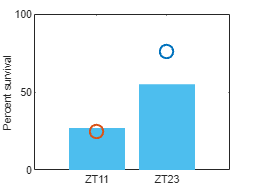


figure;
set(gca, 'Fontsize',8, 'FontName', 'Arial'); box on; hold on;
bar_name = categorical({'ZT11','ZT23'});
bar_name = reordercats(bar_name, {'ZT11', 'ZT23'});
bar_data = [survival_ratio_11, survival_ratio_23];
% bar_name = categorical({'ZT11', 'ZT23', 'ZT11-KO', 'ZT23-KO'});
% bar_name = reordercats(bar_name, {'ZT11', 'ZT23', 'ZT11-KO', 'ZT23-KO'});
% bar_data = [survival_ratio_11, survival_ratio_23, survival_ratio_11_ko, survival_ratio_23_ko];
bar(bar_name, bar_data, 'FaceColor', '#4DBEEE', 'EdgeColor', 'none');

% survival_data = [25, 76, 38, 22];
survival_data = [25, 76];
% color4 = [142 207 201; 250 127 111; 255 190 122; 130 176 210] ./ 255;
color2 = [0.8500 0.3250 0.0980; 0 0.4470 0.7410];
scatter(bar_name, survival_data, 100, color2, 'o', 'LineWidth', 1.5);
ylim([0 100]);
yticks([0 50 100]);
ylabel('Percent survival', 'Fontsize',8, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
hold off;